close all;
clc        % clear commmand window
clear      % clear MATLAB workspace

## Set up robot control system (code that runs once)

img = imread('TestPool.png'); % load oval image 
grayimage = im2gray(img);       % convert to grayscale
bwimage = grayimage < 0.5;      % convert to black and white

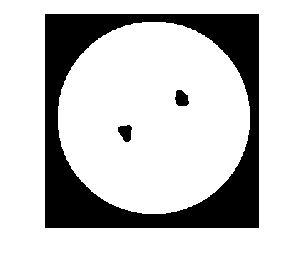

SE = strel("disk",15);
map = imclose(bwimage, SE);
map = imcomplement(map);
imshow(map)

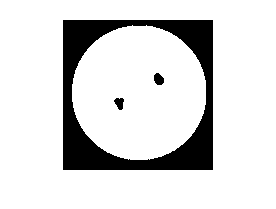


map = imresize(map,[150,150]);
imshow(map)


initial_pose = [200 70]/2;
goal_point = [100 250]/2;

k = 1;


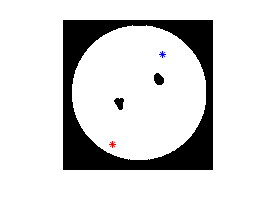

robo_pose = initial_pose;
imshow(map);
hold on
plot(robo_pose(1),robo_pose(2),'b*')
plot(goal_point(1),goal_point(2),'r*')
hold off

load('potentials.mat')

[xdim, ydim]=size(map);
potential_attractions = zeros(xdim,ydim);
for x = 1:xdim
    for y = 1:ydim
        potential_attractions(x,y) = Uattraction(goal_point, [x,y], .001);
%         end
    end
end


h = surf(potential_attractions)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 … ]
           YData: [150×1 double]
           ZData: [150×150 double]
           CData: [150×150 double]

  Show all properties


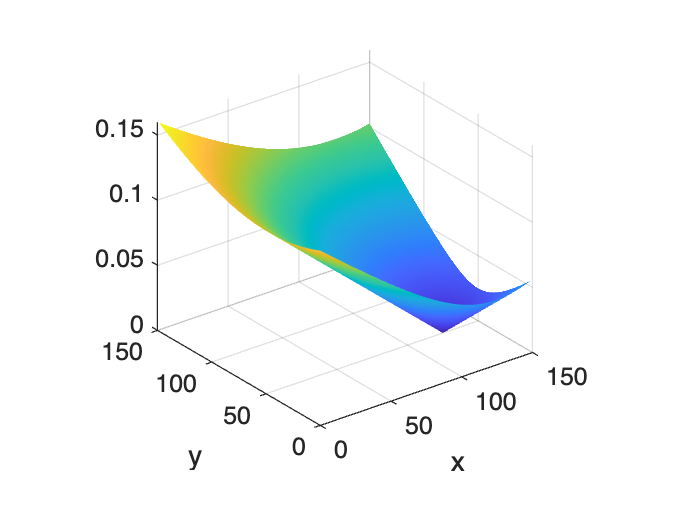

xlabel('x')
ylabel('y')
set(h,'LineStyle','none')

% d0 = 5;
% kp = 0.1;
% [xdim, ydim]=size(map);
% potential_repulsions = zeros(xdim,ydim);
% for x = 1:xdim
%     for y = 1:ydim
%         if map(x,y) == 1
%             %this is an obstacle point
%             for xr = 1:xdim
%                 for yr = 1:ydim
%                     if xr ~= x || yr ~= y
%                         potential_repulsions(xr,yr) =  potential_repulsions(xr,yr) + Urepulsion([xr yr], [x y], d0, kp);
% 
%                     end
%                 end
%             end
%         end
%     end
% end


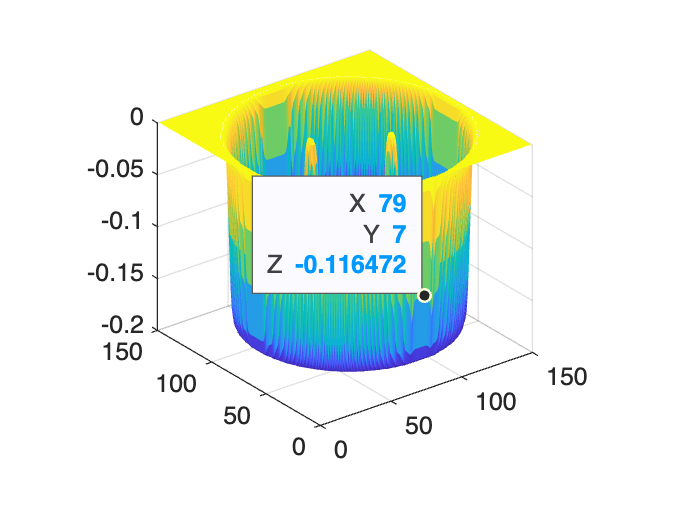

surf(-potential_repulsions,'LineStyle','none')
hold off

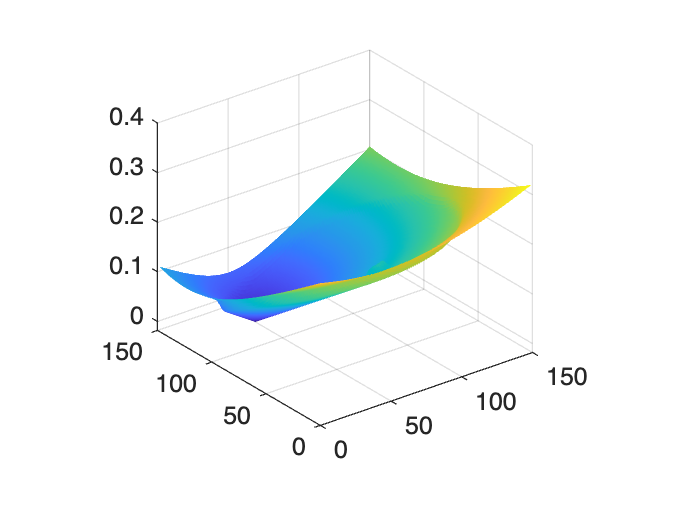

potentials = potential_attractions*2 - potential_repulsions/10;
potentials = potentials';
surf(potentials,'LineStyle','none')

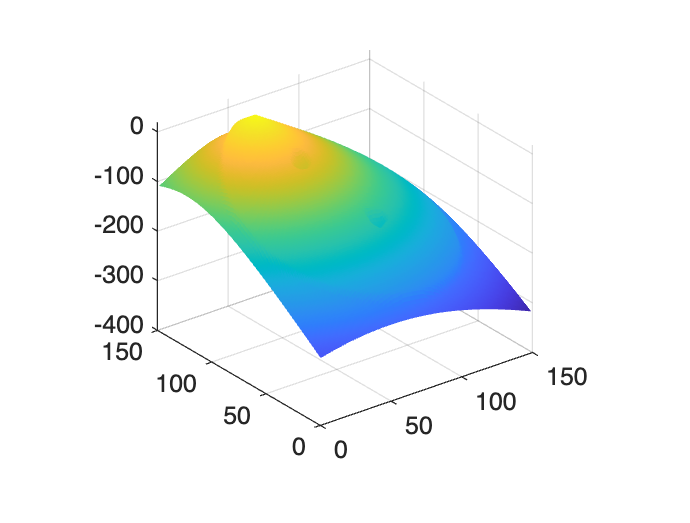

potentials_scaled = -1000*potentials;
surf(potentials_scaled,'LineStyle','none')
hold off

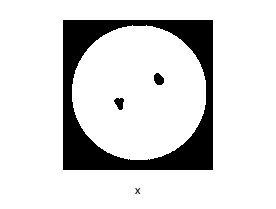

spacing = 5;
[X,Y]=meshgrid(1:spacing:size(map,1), 1:spacing:size(map,2));
[DX,DY] = gradient(potentials_scaled);
figure
imshow(map)
xlabel('x')

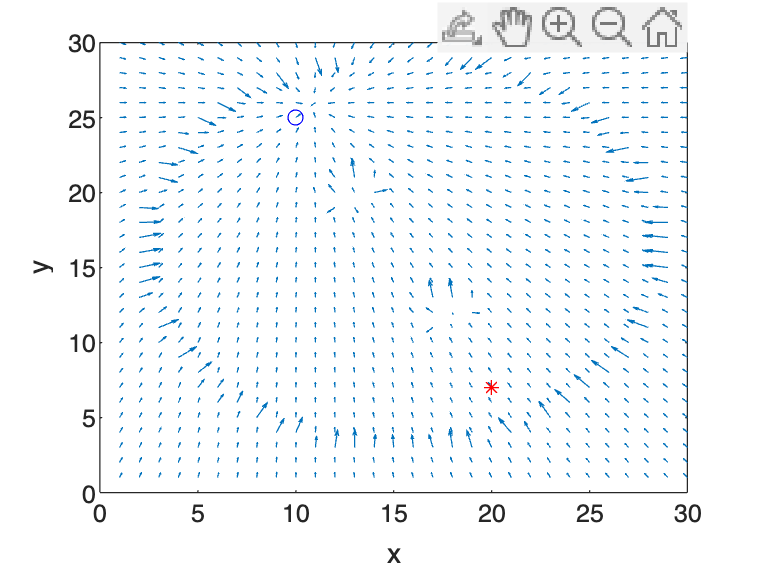

figure
quiver(DX(1:spacing:end,1:spacing:end),DY(1:spacing:end,1:spacing:end))
hold on;
plot(initial_pose(1)/5,initial_pose(2)/5,'r*')
plot(goal_point(1)/5, goal_point(2)/5,'bo')
xlabel('x')
ylabel('y')
hold off

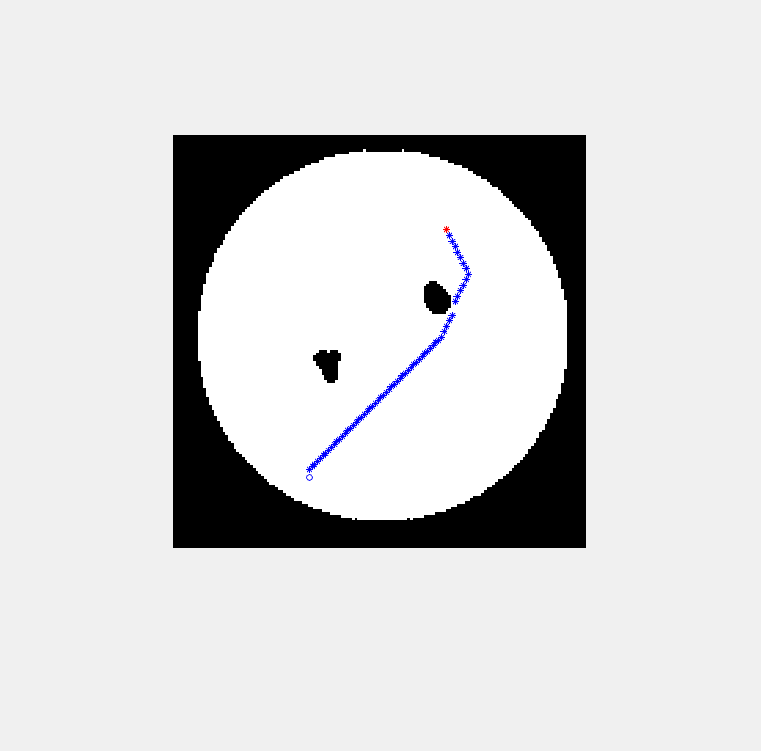


robo_pose = initial_pose;
ks = 1;
figure('Name','Path','Visible','on')

imshow(map);
hold on;
plot(initial_pose(1),initial_pose(2),'r*')
plot(goal_point(1), goal_point(2),'bo')
pause(0.5);

while norm(robo_pose-goal_point) > 3
    dx = DX(robo_pose(1),robo_pose(2));
    if dx > 5
        dx = 5;
    elseif dx < 1 && dx >= 0
        dx = 1;
    elseif dx < 0 && dx > -1
        dx = -1;
    end
    dy = DY(robo_pose(1),robo_pose(2));
    if dy > 5
        dy = 5;
    elseif dy < 1 && dx >= 0
        dy = 1;
    elseif dy < 0 && dy > -1
        dy = -1;

    end
    robo_pose(1) = robo_pose(1) + dx*ks;
    robo_pose(2) = robo_pose(2) + dy*ks;
    robo_pose(1) = round(robo_pose(1));
    robo_pose(2) = round(robo_pose(2));
%     disp(robo_pose);
    plot(robo_pose(1),robo_pose(2),'b*')
    hold on
    drawnow
    pause(0.1)
end
hold off

Function to calculate attraction potential field

function Ua = Uattraction(goal_point, robo_point, ka)
% to do include concial
    Ua = ka*norm(goal_point-robo_point);
end

function to calculate repulsive potential field

function Up = Urepulsion(robo_point, obstacle_point, d0, kp)
    dist = norm(robo_point-obstacle_point);
    if dist < d0
        Up = kp*(1/(dist+.5) - 1/d0)^2;
    else
        Up = 0;
    end
end